[x, fs] = audioread("1_stick.m4a")

x =          0
         0
   -0.0000
   -0.0000
   -0.0000
         0
    0.0000
    0.0000
    0.0000
         0


fs = 48000

%[x, fs] = audioread("26:9_1_tandsticka.mp3")

x = x(:, 1);

N = length(x);
t = (0:N-1)/fs;
N/fs

ans = 7.5080

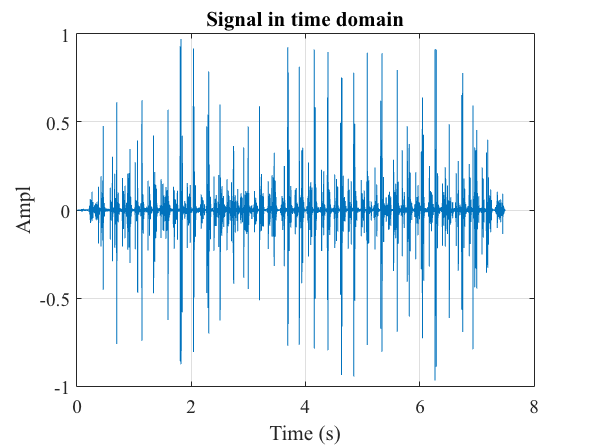

%plot time domain signal
plot(t, x)
grid on 
set(gca, "FontName", 'Time New Roman', "FontSize", 12)
xlabel("Time (s)")
ylabel("Ampl")
title("Signal in time domain")

%stats information
maxValue = max(x)

maxValue = 0.9696

minValue = min(x)

minValue = -0.9668

meanValue = mean(x)

meanValue = 2.7568e-06

stdValue = std(x)

stdValue = 0.0403

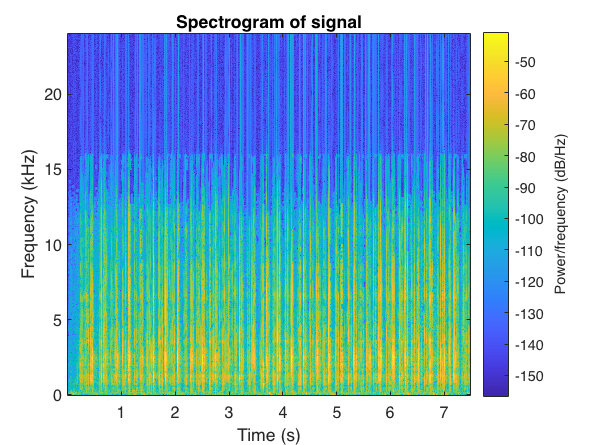

spectrogram(x, 1012, 512, 1024, fs, "yaxis")
title("Spectrogram of signal")